## drEEM 1.0.0 tutorial - How to work with the new drEEM toolbox

The drEEM toolbox  update v1.0.0 was developed on the basis of 10 years exerperience with the drEEM toolbox. It is no longer backwards compatible to drEEM versions 0.6.5 or older due to significant changes. We  use recent MATLAB features that make the toolbox more reliable and forward compatible. The toolbox therefore requires Matlab R2023b or newer.

This tutorial aims to introduce the core functions to its users. Note that it is not a tutorial on other topics, such as scatter excision, outlier diagnosis, or PARAFAC.

### Importing files

Two functions are responsible for data import. These are `importeems` and `importabsorbance`. These functions import measurement files and create the data sets (of the class `drEEMdataset`) that the you will need to work with the toolbox. This new class helps to create a standardized format for the datasets that avoids errors and makes datasets behave predicably.

To start, we will import several samples that were collected on a Horiba AquaLog (fluorometer + spectrophotometer).

cd(fileparts(matlab.desktop.editor.getActiveFilename))
clearvars
cd demofiles_AL_HYI\
samples=importeems('* - Waterfall Plot Sample.dat');

Checking wavelength integrity of data set
1/55: HE01 (01) (1.5 sec. remaining)
2/55: HE02 (01) (1.31 sec. remaining)
3/55: HE03 (01) (1.55 sec. remaining)
4/55: HE04 (01) (2.13 sec. remaining)
5/55: HE05 (01) (2.39 sec. remaining)
6/55: HE06 (01) (2.43 sec. remaining)
7/55: HE07 (01) (2.1 sec. remaining)
8/55: HE08 (01) (2.3 sec. remaining)
9/55: HE09 (01) (2.09 sec. remaining)
10/55: HE10 (01) (1.64 sec. remaining)
11/55: HE11 (01) (1.48 sec. remaining)
12/55: HE12 (01) (1.15 sec. remaining)
13/55: HE13 (01) (1.51 sec. remaining)
14/55: HE14 (01) (1.58 sec. remaining)
15/55: HE15 (01) (1.15 sec. remaining)
16/55: HE16 (01) (1 sec. remaining)
17/55: HE17 (01) (1.13 sec. remaining)
18/55: HE17.2 (01) (0.89 sec. remaining)
19/55: HE17.3 (01) (1.05 sec. remaining)
20/55: HE18 (01) (0.94 sec. remaining)
21/55: HE19 (02) (0.81 sec. remaining)
22/55: HE20 (01) (1.16 sec. remaining)
23/55: HE21 (01) (1.24 sec. remaining)
24/55: HE22 (01) (1.04 sec. remaining)
25/55: HE23 (01) (0.85 sec. remai

blanks=importeems('* - Waterfall Plot Blank.dat');

Checking wavelength integrity of data set
1/55: HE01 (01) (1.81 sec. remaining)
2/55: HE02 (01) (1.63 sec. remaining)
3/55: HE03 (01) (1.89 sec. remaining)
4/55: HE04 (01) (2.27 sec. remaining)
5/55: HE05 (01) (1.61 sec. remaining)
6/55: HE06 (01) (1.43 sec. remaining)
7/55: HE07 (01) (1.28 sec. remaining)
8/55: HE08 (01) (1.65 sec. remaining)
9/55: HE09 (01) (1.94 sec. remaining)
10/55: HE10 (01) (1.38 sec. remaining)
11/55: HE11 (01) (1.27 sec. remaining)
12/55: HE12 (01) (1.63 sec. remaining)
13/55: HE13 (01) (1.56 sec. remaining)
14/55: HE14 (01) (1 sec. remaining)
15/55: HE15 (01) (1.06 sec. remaining)
16/55: HE16 (01) (1.4 sec. remaining)
17/55: HE17 (01) (1.02 sec. remaining)
18/55: HE17.2 (01) (1.18 sec. remaining)
19/55: HE17.3 (01) (1.03 sec. remaining)
20/55: HE18 (01) (0.86 sec. remaining)
21/55: HE19 (02) (1.07 sec. remaining)
22/55: HE20 (01) (1.11 sec. remaining)
23/55: HE21 (01) (0.9 sec. remaining)
24/55: HE22 (01) (0.85 sec. remaining)
25/55: HE23 (01) (0.76 sec. rema

absorbance=importabsorbance('* - Abs Spectra Graphs.dat');

Checking wavelength integrity of data set
1/55: HE01 (01) (1.33 sec. remaining)
2/55: HE02 (01) (1.07 sec. remaining)
3/55: HE03 (01) (0.97 sec. remaining)
4/55: HE04 (01) (0.78 sec. remaining)
5/55: HE05 (01) (1.07 sec. remaining)
6/55: HE06 (01) (0.71 sec. remaining)
7/55: HE07 (01) (0.75 sec. remaining)
8/55: HE08 (01) (0.71 sec. remaining)
9/55: HE09 (01) (0.73 sec. remaining)
10/55: HE10 (01) (0.88 sec. remaining)
11/55: HE11 (01) (0.66 sec. remaining)
12/55: HE12 (01) (0.77 sec. remaining)
13/55: HE13 (01) (0.67 sec. remaining)
14/55: HE14 (01) (0.62 sec. remaining)
15/55: HE15 (01) (0.56 sec. remaining)
16/55: HE16 (01) (0.67 sec. remaining)
17/55: HE17 (01) (0.51 sec. remaining)
18/55: HE17.2 (01) (0.55 sec. remaining)
19/55: HE17.3 (01) (0.48 sec. remaining)
20/55: HE18 (01) (0.62 sec. remaining)
21/55: HE19 (02) (0.55 sec. remaining)
22/55: HE20 (01) (0.44 sec. remaining)
23/55: HE21 (01) (0.36 sec. remaining)
24/55: HE22 (01) (0.37 sec. remaining)
25/55: HE23 (01) (0.35 sec.

metadata=readtable("Biogeochemie_ODV-Excel-Tabelle_Ergebnisse.xlsx",Sheet="Tabelle2")

metadata = 47×32 table
      dkId          Var2        dkLabel1    dkLabel2    matlab    Station      mon_day_yr       hh_mm     Lon__E_    Lat__N_    Bot_Depth_m_    Depth_m_    Secchi    Chlorophyll    O2Winkler    Phosphat__mol_L_    Silikat__mol_L_    Nitrat__mol_L_    DOC__MC_    TDN__MN_    DIN__MN_    DON__MN_    C_N_Verh_ltnis    Schwebstoffgehalt_mg_L_    Salzgehalt_psu_    Temperatur__C_    Press_dbar_    Sigma     Oxygen_ml_l_    OxygSat_proz_    Transmission_proz_</

The drEEMdataset object features a field to specify the status of spectral correction. By default this is set to unknown, but the AquaLog provides spectrally corrected data. So we change the options in the three datasets accordingly.

cd ..

The structures `samples`, `blanks`, and `absorbance` contain the data after import. To inspect, run one or both of these commands:

%openvar("samples") % or
disp(samples)

  drEEMdataset with properties:

        instrumentInfo: [0×0 struct]
       measurementInfo: [0×0 struct]
               history: [1×1 struct]
                     X: [55×125×73 double]
                   abs: []
           suppSpectra: []
              filelist: {55×1 cell}
                     i: [55×1 double]
                    Ex: [73×1 double]
                    Em: [125×1 double]
                   nEx: 73
                   nEm: 125
               absWave: [0×1 double]
       suppSpectraAxis: [0×1 double]
               nSample: 55
                models: [0×1 drEEMmodel]
              metadata: [55×2 table]
                 split: [0×0 drEEMdataset]
    spectralCorrection: 'applied by instrument software'
         IFEcorrection: 'not applied'
      blankSubtraction: 'not applied'
     signalCalibration: 'not applied'
      scatterTreatment: 'not applied'
         signalScaling: 'original scale'
            

disp(samples.toolboxdata) % Read-only properties

            version: "1.0.0"
               host: 'aqua-cb-urbw23'
      matlabVersion: '23.2.0.2485118 (R2023b) Update 6'
    matlabToolboxes: [1×20 struct]



### Ensuring file alignment

In order to do IFE corrections and blank subtractions, we need to ensure that the filelists consist of the same samples in in the same sequence. An instrument like the AquaLog makes sure that all three files are exported, but it is always required to check that the same samples are present and that the e.g. 1st sample in each dataset corresponds to the same sample. `aligndataset` aims to make this job easier for you. It automatically deletes samples that have sample, blank, or absorbance spectrum missing and ensures that the sequence of samples is the same in all datasets. At the end of this process, we can delete the structure `absorbance`; it is no longer needed.

[samples,blanks,absorbance]=alignsamples(samples,blanks,absorbance);

dataset 1: No action necessary. All files between supplied datasets had same names.
dataset 2: No action necessary. All files between supplied datasets had same names.
dataset 3: No action necessary. All files between supplied datasets had same names.


% The next two lines transfer the absorbance data into the sample EEM
% dataset
samples.absWave=absorbance.absWave;
samples.abs=absorbance.abs;
clearvars absorbance

### Import metadata

samples.filelist=erase(samples.filelist,{' (01)'});
metadata.Var2=strtrim(erase(metadata.Var2,"'"));
samples=associatemetadata(samples,metadata,'Var2');

                     drEEMdataset    imported metadata table
                     ____________    _______________________

    No. samples           55                   47           
    Total matched         43                   43           
    % matched             78                   91           



### Process absorbance data

Before inner filter effects (IFEs) can be corrected, we need to make sure the absorbance data is of sufficient quality and covers the relevant wavelength needed for the IFE correction.

Absorbance and fluoresence cover different wavelength areas. The EEM will be cut during the IFE correction unless absorbance is extrapolated. This should only be done if CDOM absorbance was measured, as extrapolation is possible due to the featureless properties of CDOM absorbance at high wavelengths.


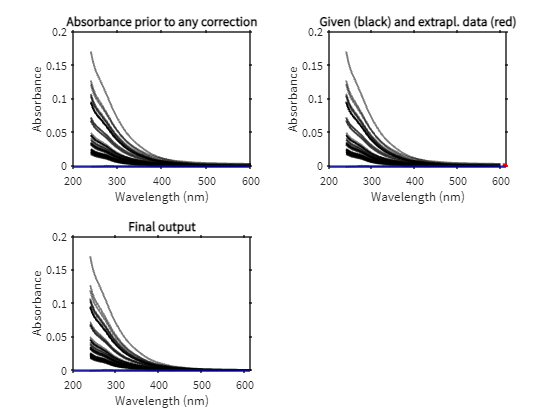

samples=processabsorbance(samples);

As you can see from the plot, the main issue of baseline offsets was taken care of and the absorbance data is now ready for futher action. 

### Inner filter effect correction

Compared to previous routines, this tutorial prioritizes IFE corrections in the sequence to do a better job of removing Raman scatter. This type of scatter is affected by IFEs and when a blank subtraction occurs before IFE correction, the subtraction can result in negative scatter residuals. The new sequence prevents this from happening.

[samples,emout,exout]=ifecorrection(samples);

### Blank subtraction

Next, in the drEEMneo sequence, we recommend the blank subtraction. `subtractblanks` takes care of all the housekeeping, so you just need to run one line of code.

samples=subtractblanks(samples,blanks);

### Raman calibration

Next in the sequence is the signal calibration. Due to ease of use, we strongly recommend the calibration of fluorescence signals by the division of the Raman scatter peak area at 350 nm. `ramancalibration` takes care of the job for you. Note that it is important to inspect the function output to ensure a reliable signal calibration.

data=ramancalibration(samples,blanks);

### Scatter treatment

The treatment of scatter is done by the function `handlescatter` (`smootheem` is deprecated). You can call

%handlescatter(data,'exploreoptions')

for decision support.

% Scatter treatment
% handlescatter(data,'exploreoptions')
opt=handlescatterOptions; % or opt=handlescatter('options');
opt.ray1 = [30 10];
opt.ram1 = [5 5];
opt.ray2 = [10 10];
opt.ram2 = [5 5];
opt.cutout = [1 0 1 0];
opt.interpolate = [0 0 0 0];
opt.d2zero = 30;
opt.negativetozero = true;
opt.samples = 'all';
opt.iopt = 'normal';
opt.plot = false;
opt.imethod = 'inpaint';

data=handlescatter(data,opt);


### Final adjustments & data set inspection

At this point, the EEMs can be denoised (`rmspikes`), useless areas be removed (`subdataset`), and other noise or problematic data can be zapped (`zapnoise`). 

% Automatic denoising of EEMs

data=rmspikes(data); % Take care that the automated procedure works well (this is not always the case)

% Cutting into an appropriate size
data=subdataset(data,[],data.Em<310|data.Em>600,data.Ex>500);

% Remove an area in one sample if desired
data = zapnoise(data,1,[350 370],[249]);


### Data visualization & exploration

Before conducting PARAFAC, it is important to visualize the data sets. The following functions can be used for this purpose.

% vieweems(data)
% specview(data)
% spectralvariance(data)
% explorevariability(data)

### PARAFAC modelling

Now it is time for PARAFAC. In drEEMneo, a new, faster PARAFAC algorithm is used (if nonnegativity constraints are used). Contrary to previous versions of the toolbox, one function takes care of all modelling (`fitparafac`). In `mode="overall"`, `fitparafac` performs the job of the now deprecated `randinitanal`.

data=scalesamples(data,2);
data=subdataset(data,1,[],[]);
data=fitparafac(data,f=2:5, ...
    starts=2, ...
    convergence=1e-2,...
    parallelization=false, ...
    mode="overall");

All diagnosis functions are united in one GUI-supported function:

viewmodels(data)
viewcompcorr(data)
data=scalesamples(data,'reverse');

This function unites `spectralloadings`, `loadingsandleverages`, `errorsandleverages`, `specsse `(all deprecated) and provides an overview over component correlations while `compcorrplot` still provides an in depth view. `splitds` is the well-known function that prepares the dataset for splitanalysis and validation: 

data=splitdataset(data)

In `mode="split"`, `fitparafac` fits models to all the validation splits prepared by `splitds`.

data=fitparafac(data,f=2:5, ...
    starts=2, ...
    convergence=1e-2,...
    parallelization=false, ...
    mode="split")

The function `splitvalidation` has received some updates that aim to provide more information on why a validation failed, and takes care to align components as good as possible for visual comparisons. This works reasonably well as long as the validation is either successfull or reasonably close to being successful.

data=splitvalidation(data,2);

openvar("data.history")
disp(struct2table(data.history))